% Plot graphs
Plot = false;
% Save praphs
Save_graph = true;

% Determine where your m-file's folder is
folder = fileparts(which("opt_problem.mlx"));
% Add that folder plus all subfolders to the path
addpath(genpath(folder));

#### GFDM parameters.

gfdm = struct;
%gfdm.K = 5; % Subcarriers
%gfdm.M = 4; % Subsymbols
gfdm.K = K;
gfdm.M = M;

SEM = "802.11ac";
Channel = 20; % Channel bandwidth (MHz)
gfdm.rms = 0; % root mean square (rms) delay spread (ns)

uti_threshold =  0.55; % Utilize rate threshold
rc_beta = 0.1; % RC filter beta

gfdm = GFDM_init(gfdm);

D = gfdm.D;

Normalized frequency $fT_s = \frac{f}{f_s}$ and normalized frequency interval $\Delta fT_s
$

delta_fTs = 0.01;
fTs_limit = (1+rc_beta)/2;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(fTs_limit,fTs_limit)
    msg = 'normalized frequency sampling interval delta_fTs can not equally spaces fTs_range';
    error(msg);
end

fTs_range = [0 fTs_limit];
fTs = -fTs_range(2):delta_fTs:fTs_range(2);

Interpolation filter $P(f)$

P = rc_filter(delta_fTs, fTs_range, rc_beta);

All combinations of $K_{\textrm{on}}$ and $M_{\textrm{on}}$ with decreasing order: $N$

The number of element used $N_{\textrm{sort}} \left(n\right)$ is the result of using $K_{\textrm{on}}$ = $\textrm{sort}\_\textrm{idx}\_K\left(n\right)$ and $M_{\textrm{on}}$ = $\textrm{sort}\_\textrm{idx}\_M\left(n\right)$.

EXCLUDING $M_{\textrm{on}} =M$.

[N_sort, sort_idx_K, sort_idx_M] = sort_N(gfdm);

#### Find the maximum used resource $N$ and its corresponding $K_{\textrm{on}}$ and $M_{\textrm{on}}$.

% Start from the first index with utilize rate grater than the utilize rate
% threshold
uti_rate = N_sort/D;
idx_start = find(uti_rate < uti_threshold, 1) - 1;

if idx_start < 2
    idx_start = 2;
end

% Loop used resources
N_counter = idx_start;
N_start = tic;

% Calculate CP and D' length
gfdm.CP = max(ceil(gfdm.rms*Channel*1e-3), 0);
gfdm.D_prime = D + gfdm.CP;

for n = idx_start:length(N_sort)

    KonMon = N_sort(n);
    gfdm.K_on = sort_idx_K(n); gfdm.M_on = sort_idx_M(n);
    fprintf("%d. K_on = %d M_on = %d N = %d \n", N_counter-idx_start+1, gfdm.K_on, gfdm.M_on, KonMon);
    fprintf("Utilize rate: %f \n", KonMon/D);

    S = Dottorro(gfdm, Channel, Channel, P, SEM, fTs);

    % Feasible set found
    if ~isnan(S(1,1))
        break;
    end

    N_counter = N_counter + 1;
end

S_20 = S;
K_on_max = gfdm.K_on;
M_on_max = gfdm.M_on;

fprintf('===============================\n');
fprintf("K_on = %s M_on = %s N = %d \n", K_on_max, M_on_max, KonMon);
fprintf("Utilized rate: %f \n", KonMon/D);
fprintf('Max utilization time: %s\n', duration([0, 0, toc(N_start)]));
fprintf('===============================\n');

#### Bisection method to find the max sampling frequency $f_s$.

all_KonMon = table;
all_KonMon = [all_KonMon; table(R, K_on, M_on, uti_rate, max_fs)];

% Bisection stop criteria
fs_criteria = 0.1;

% Effective data rate when fs=Channel
R_max_all = (KonMon/(D+gfdm.CP)) * Channel;
idx = 1;
while (KonMon/(K*M)) > (R_max_all/(2*Channel))

    B_start = tic;

    fprintf("%d. K_on = %d M_on = %d N = %d \n", idx, gfdm.K_on, gfdm.M_on, KonMon);
    fprintf("Utilize rate: %f \n", uti_rate);

    S = Dottorro_max_gap(gfdm, Channel, Channel, P, SEM, fTs);

    % precede on bisection if f_s = Channel works
    if ~isnan(S(1,1))
        fs_low = Channel;
        fs_up = 2*fs_low;
        fs_diff = fs_criteria;
        fs_mid = fs_up;
        fs = 0;

        % Effective data rate when fs=Channel for this K_on M_on
        R_max = (KonMon/(D+gfdm.CP)) * Channel;

        while fs_diff >= fs_criteria

#### Dottorro iterative algorithm & optimization problem


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


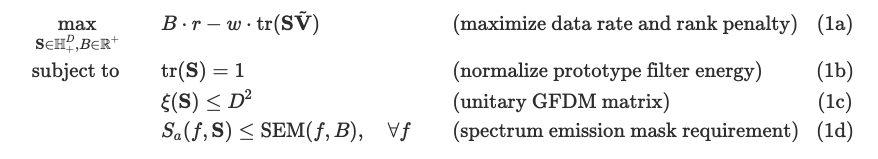

            % Calculate CP and D' length
            gfdm.CP = max(ceil(gfdm.rms*fs_mid*1e-3), 0);
            gfdm.D_prime = gfdm.D + gfdm.CP;

            % R for this fs_mid
            R_temp = (KonMon/(D+gfdm.CP)) * fs_mid;

            if R_temp > R_max
                S = Dottorro_max_gap(gfdm, fs_mid, Channel, P, SEM, fTs);
                if ~isnan(S(1,1))
                    % Bisection update if R is larger
                    fs_low = fs_mid;
                    fs = fs_mid;

                    R_max = (KonMon/(D+gfdm.CP)) * fs;
                    S_solved(:, :) = S;

                    if Plot == 1
                        switch SEM
                            case "802.11ac"
                                mask_dB = SEM_ac(fTs, fs(idx), Channel);
                            case "802.11b"
                                mask_dB = SEM_b(fTs, fs(idx), Channel);
                        end
                        mask_linear = db2pow(mask_dB);
                        S_a_S = PSD_S(gfdm, S, fs(idx), zeros(size(P)), fTs, P);
                        plot_PSD(gfdm, S_a_S, mask_dB, fTs, fs(idx));
                    end
                else
                    % Bisection update if infeasible
                    fs_up = fs_mid;
                end
            else
                % Bisection update if infeasible
                fs_up = fs_mid;
            end

            fs_diff = fs_up - fs_low;
            % Midpoint
            fs_mid = (fs_up + fs_low)/2;
        end
    else
        R_max = 0; fs = 0;
    end

    if R_max > R_max_all
        R_max_all = R_max;
    end
    all_KonMon = [all_KonMon; table(R_max, K_on, M_on, uti_rate, fs)];

    fprintf("K_on: %d M_on: %d R: %s \n",K_on, M_on, R_max);
    fprintf('Bisection time: %s\n', duration([0, 0, toc(B_start)]));

    n = n + 1;
    idx = idx + 1;

    KonMon = N_sort(n);
    gfdm.K_on = sort_idx_K(n); gfdm.M_on = sort_idx_M(n);
    K_on = gfdm.K_on; M_on = gfdm.M_on;
    uti_rate = KonMon/D;
end

total_time = duration([0, 0, toc(N_start)]);
fprintf('Total time: %s\n', total_time);

% Get the K_on, M_on with biggest R
A = table2array(T);
[R_max_all, R_max_idx] = max(A(:, 1));
K_on_max = A(2, idx); M_on_max = A(3, idx);
fprintf('Max R: %s K_on: %d M_on: %d, \n', R_max_all, K_on_max, M_on_max);

% Assign S and g
if max_fs ~= 20 % If bisection found an answer
    S = S_solved(:, :, idx);
else
    S = S_20;
end
g = S2g(S);

switch SEM
    case "802.11ac"
        mask_dB = SEM_ac(fTs, max_fs, Channel);
    case "802.11b"
        mask_dB = SEM_b(fTs, max_fs, Channel);
end
mask_linear = db2pow(mask_dB);
% P = rc_filter(delta_fTs, fTs_range, rc_beta);
psd_temp = zeros(size(P));
% g = S2g(S); G = g2chaG(g, gfdm.K, gfdm.M);
% S_a = PSD_G(gfdm, G, f_range, delta_f);
S_a_S = PSD_S(gfdm, S, max_fs, psd_temp, fTs, P);

if Save_graph
    save_PSD(gfdm, S_a_S, mask_dB, fTs, max_fs, R);
end

if Plot
     
    plot_PSD(gfdm, S_a_S, mask_dB, fTs, max_fs, R);
end

% to open the figure
% openfig('newout.fig','new','visible')